# Continuation of quasiperiodic invariant tori

Two-dimensional quasiperiodic invariant tori are characterized by a parallel flow with irrational rotation number. In terms of a suitably defined torus function, the dynamics on the torus may be described by an invariant circle that is mapped to itself by the flow, such that the flow is equivalent to a rigid rotation on the circle.

We obtain an approximate description of a quasiperiodic invariant torus in terms of a Fourier representation of the invariant circle and a finite collection of trajectory segments based at points on the invariant circle. The rigid rotation imposes an all-to-all coupled system of boundary conditions on the collection of trajectory segments.

Here we consider Van der Pol oscillator subject to harmonic excitation as follows


$$\ddot{x}-c(1-x^2)\dot{x}+x=a\cos\Omega t$$


and we are interested in the quasiperiodic response of such a system. We use this example to demonstrate the functionality of the tor toolbox

- **ode_isol2tor**: continuation of tori from a gusss initial solution

- **ode_tor2tor**: continuation of tori from a stored torus solution

- **ode_BP2tor**: continuation of tori along the secondary branch of tori of a branch point 

- *post-processing*: tor_read_solution, plot_torus

## ode_isol2tor

**Construct the guess of initial solution**

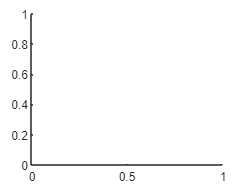

% pnames = [  om     c     a ]
p0       = [ 1.5111; 0.11; 0.1 ];

T_po = 2*pi; % Approximate period
N    = 10;   % 2N+1 = Number of orbit segments
tout = linspace(0, T_po, 2*N+2);

T_ret = 2*pi/p0(1); % return time = 2*pi/om
tt    = linspace(0,1,10*(2*N+1))';
t1    = T_ret*tt;
x0    = zeros(numel(tt),2,2*N+1);

figure; hold on

for i=1:2*N+1 % For each point on orbit, flow for return time and reconstitute 3D trajectory
  x1       = [2*cos(tout(i)) 2*sin(tout(i))];
  [~, x1] = ode45(@(t,x) vdp(t,x,p0), 10*t1, x1); % Transient simulation
  [~, x1] = ode45(@(t,x) vdp(t,x,p0), t1, x1(end,:));
  x0(:,:,i) = x1;
  plot3(x1(:,1),t1,x1(:,2),'r-');
end

Error using demo
Simulink model 'vdp' was called with incorrect number of arguments

Error in odearguments (line 92)
f0 = ode(t0,y0,args{:});   % ODE15I sets args{1} to yp0.

Error in ode45 (line 107)
  odearguments(odeIsFuncHandle,odeTreatAsMFile,


varrho = T_ret/T_po;

**Construct continuation problem**

prob = coco_prob();
prob = coco_set(prob, 'tor', 'autonomous', false);
prob = coco_set(prob, 'coll', 'NTST', 40);
prob = coco_set(prob, 'cont', 'NAdapt', 0, 'h_max', 2, 'PtMX', 60);
torargs = {@vdp @vdp_DFDX @vdp_DFDP @vdp_DFDT t1 x0 {'Om2','c','a','om1','om2','varrho'} [p0' -2*pi/T_po p0(1) -varrho]};
% we choose negative om1 above because the rotation direction is opposite.
% In other words, the value of om1 can be both positive and negative
prob = ode_isol2tor(prob, '', torargs{:});

fprintf('\n Run=''%s'': Continue family of quasiperiodic invariant tori.\n', ...
  'torus');

coco(prob, 'vdP_torus', [], 1, {'a','Om2','om2','om1', 'varrho','c'}, {[0.1 2] [1 2]});

## ode_tor2tor: restart from previous solution

bd  = coco_bd_read('vdP_torus');
lab = coco_bd_labs(bd, 'EP');
lab = max(lab);
prob = coco_prob();
prob = coco_set(prob, 'cont', 'NAdapt', 5, 'h_max', 2, 'PtMX', 60);
prob = ode_tor2tor(prob, '', 'vdP_torus', lab);

fprintf('\n Run=''%s'': Continue family of quasiperiodic invariant tori.\n', ...
  'vdP_torus_varrho');

coco(prob, 'vdP_torus_varrho', [], 1, {'a','Om2','om2','varrho','om1','c'}, {[0.1 2] [1 2]});

## ode_BP2tor: switch to secondary branch

bd  = coco_bd_read('vdP_torus_varrho');
lab = coco_bd_labs(bd, 'BP');
lab = lab(1);
prob = coco_prob();
prob = coco_set(prob, 'cont', 'NAdapt', 0, 'h_max', 2, 'PtMX', 60);
prob = ode_BP2tor(prob, '', 'vdP_torus_varrho', lab);

fprintf('\n Run=''%s'': Continue family of quasiperiodic invariant tori.\n', ...
  'vdP_torus_varrho_BP');

coco(prob, 'vdP_torus_varrho_BP', [], 1, {'a','Om2','om2','varrho','om1','c'}, {[0.1 2] [1 2]});

## Visualization of results

Plot of continuation path

figure; hold 
coco_plot_bd('vdP_torus_varrho', 'a', 'om2');hold on
coco_plot_bd('vdP_torus_varrho_BP', 'a', 'om2'); % secondary branch
grid on

Here we show how to use tor_read_solution

[sol, data] = tor_read_solution('', 'vdP_torus_varrho_BP', 1);
tube = sol.xbp;
tube = permute(tube, [1,3,2]);
tbp  = repmat(sol.tbp, [1,data.nsegs+1]);
figure; hold on
surf(tube(:,:,1), tbp, tube(:,:,2), 'FaceAlpha', 0.7, ...
    'MeshStyle', 'column', 'LineStyle', '-', 'EdgeColor', 0.6*[1 1 1], ...
    'LineWidth', 0.5);
plot3(tube(1,:,1), zeros(data.nsegs+1,1), tube(1,:,2), 'LineStyle', '-', 'LineWidth', 2, ...
    'Color', 'black', 'Marker', '.', 'MarkerSize', 12);
plot3(tube(end,:,1), tbp(end)*ones(data.nsegs+1,1), tube(end,:,2), 'LineStyle', '-', 'LineWidth', 2, ...
    'Color', 'blue', 'Marker', '.', 'MarkerSize', 12);
xlabel('$x$','Interpreter',"latex");
ylabel('$t$','Interpreter',"latex");
zlabel('$\dot{x}$','Interpreter',"latex")
view([50 15]); grid on

Or you may simply call plot_torus for plotting

plot_torus('','vdP_torus_varrho_BP', 1, [1 2]);

## Remarks

- The toolbox also supports the computation of torus in autonomous system (two phase conditions are needed). Please see demo langford for more details.

- The continuation in this demo starts from an initial guess. It is not trivial to construct good initial guess. On the other hand, TR bifurcation points could be detected in the cotinuation of periodic orbits. TR point indicates the apperance of quasi-periodic resposne. ode_TR2tor is developed as well to switch continuation from periodic orbits to tori. Please see demoTR in current folder for more details.